# HW3

### Sommario

### Introduzione

L’obiettivo principale di questo progetto è quello di generare dei dataset di rendimenti a partire da una distribuzione nota e verificare l’impatto degli errori di stima sulla ricchezza terminale di un investimento. Per farlo andremo a confrontare il portafoglio teoricamente ottimo con quello ricavato dopo aver stimato i parametri. Prima di tutto, andiamo ad importare dei dati reali relativi ad alcuni stock di discreta rilevanza in finanza. Così facendo, il nostro portafoglio avrà dei pesi in stock reali e potremmo avere un’idea verosimile di quello che accade quando si va ad investire in questi ultimi. Nello specifico il nostro portafoglio sarà costituito al più da dieci diversi asset, ciascuno relativo ad una compagnia. Le compagnie che abbiamo scelto sono (con i rispettivi simboli):

AAPL  Apple, Inc.

SBUX  Starbucks, Inc.

MSFT  Microsoft, Inc.

CSCO  Cisco Systems, Inc.

QCOM  QUALCOMM Incorporated

FB    Facebook, Inc.

AMZN  Amazon.com, Inc.

TSLA  Tesla, Inc.

AMD   Advanced Micro Devices, Inc.

ZNGA  Zynga Inc.

I dati sono relativi all’indice di chiusura delle diverse compagnie negli ultimi 5 anni per tutti i giorni lavorativi, che per ciascun anno corrispondono a circa 250. Ad esempio, possiamo osservare il comportamento dell'indice per la compagnia Microsoft, nel periodo dei 5 anni considerati, con la variazione giornaliera. Nelle due figure successive possiamo osservare l’andamento giornaliero per ciascuna azienda, prima per tutto il periodo che stiamo considerando, e poi solamente per un intervallo (di due anni) compreso all’interno di questo periodo, nello specifico questo va dal 3 Novembre 2017 al 3 Novembre del 2019.  

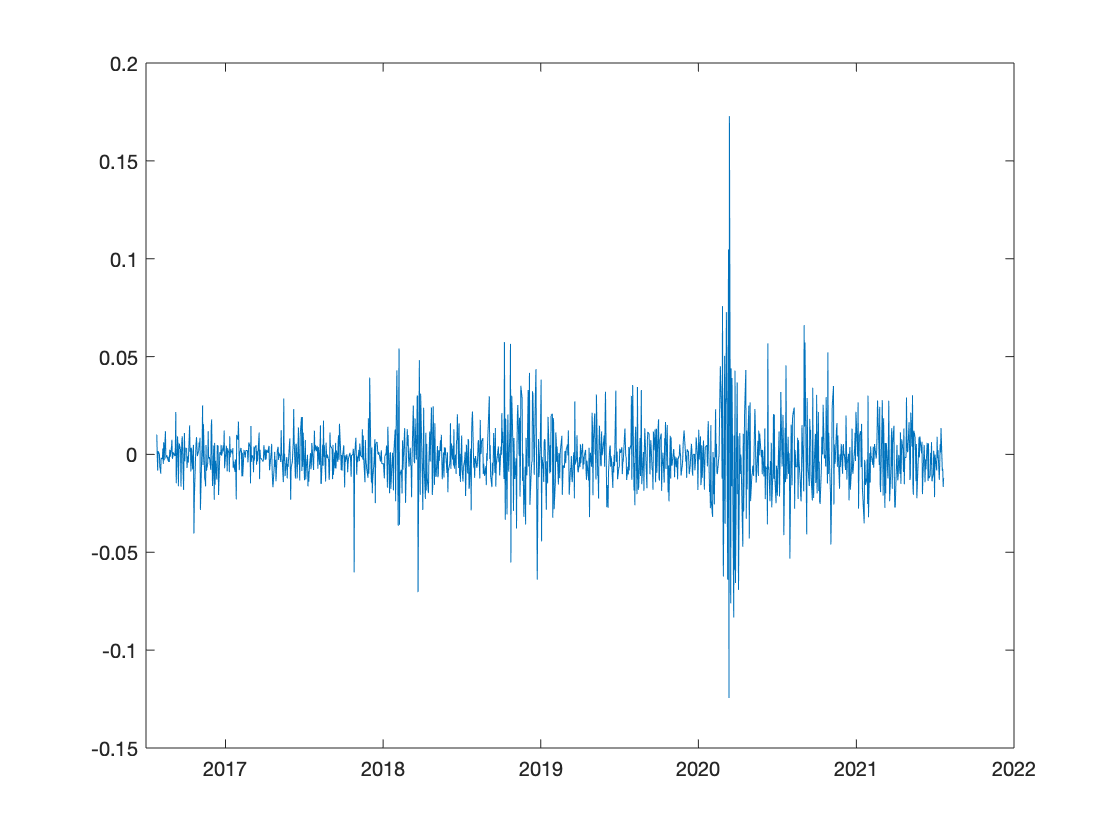

clc
clear all
close all
list_stock= ["AAPL","SBUX","MSFT","CSCO","QCOM","FB","AMZN","TSLA","AMD","ZNGA"];
num_asset = length(list_stock);

T = readtable(strcat('stock/',list_stock(3),".csv"),'PreserveVariableNames',0);
values = str2double(strrep(string(T.Close_Last),'$',''));
date = datetime(T.Date);
var = (values(2:end)-values(1:end-1))./values(1:end-1);
f0=figure;
plot(date(2:end),var)


%per eliminare warning nella creazione delle table
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')

figure1=figure('Position', [0, 0, 1100, 500]);
subplot(1, 2, 1)
returns = zeros(num_asset,1257);
for i = 1:length(list_stock)
    T = readtable(strcat('stock/',list_stock(i),".csv"));
    date = flip(datetime(T.Date));
    date(1) = [];
    values = flip(str2double(strrep(string(T.Close_Last),'$','')));
    returns(i,:) = (values(2:end)-values(1:end-1))./values(1:end-1);
    hold on
    plot(date,returns(i,:))
end
title('Asset returns');
legend(list_stock);
startDate = date(300)

startDate = datetime
   10/03/2017


finishDate = date(803)

finishDate = datetime
   10/03/2019


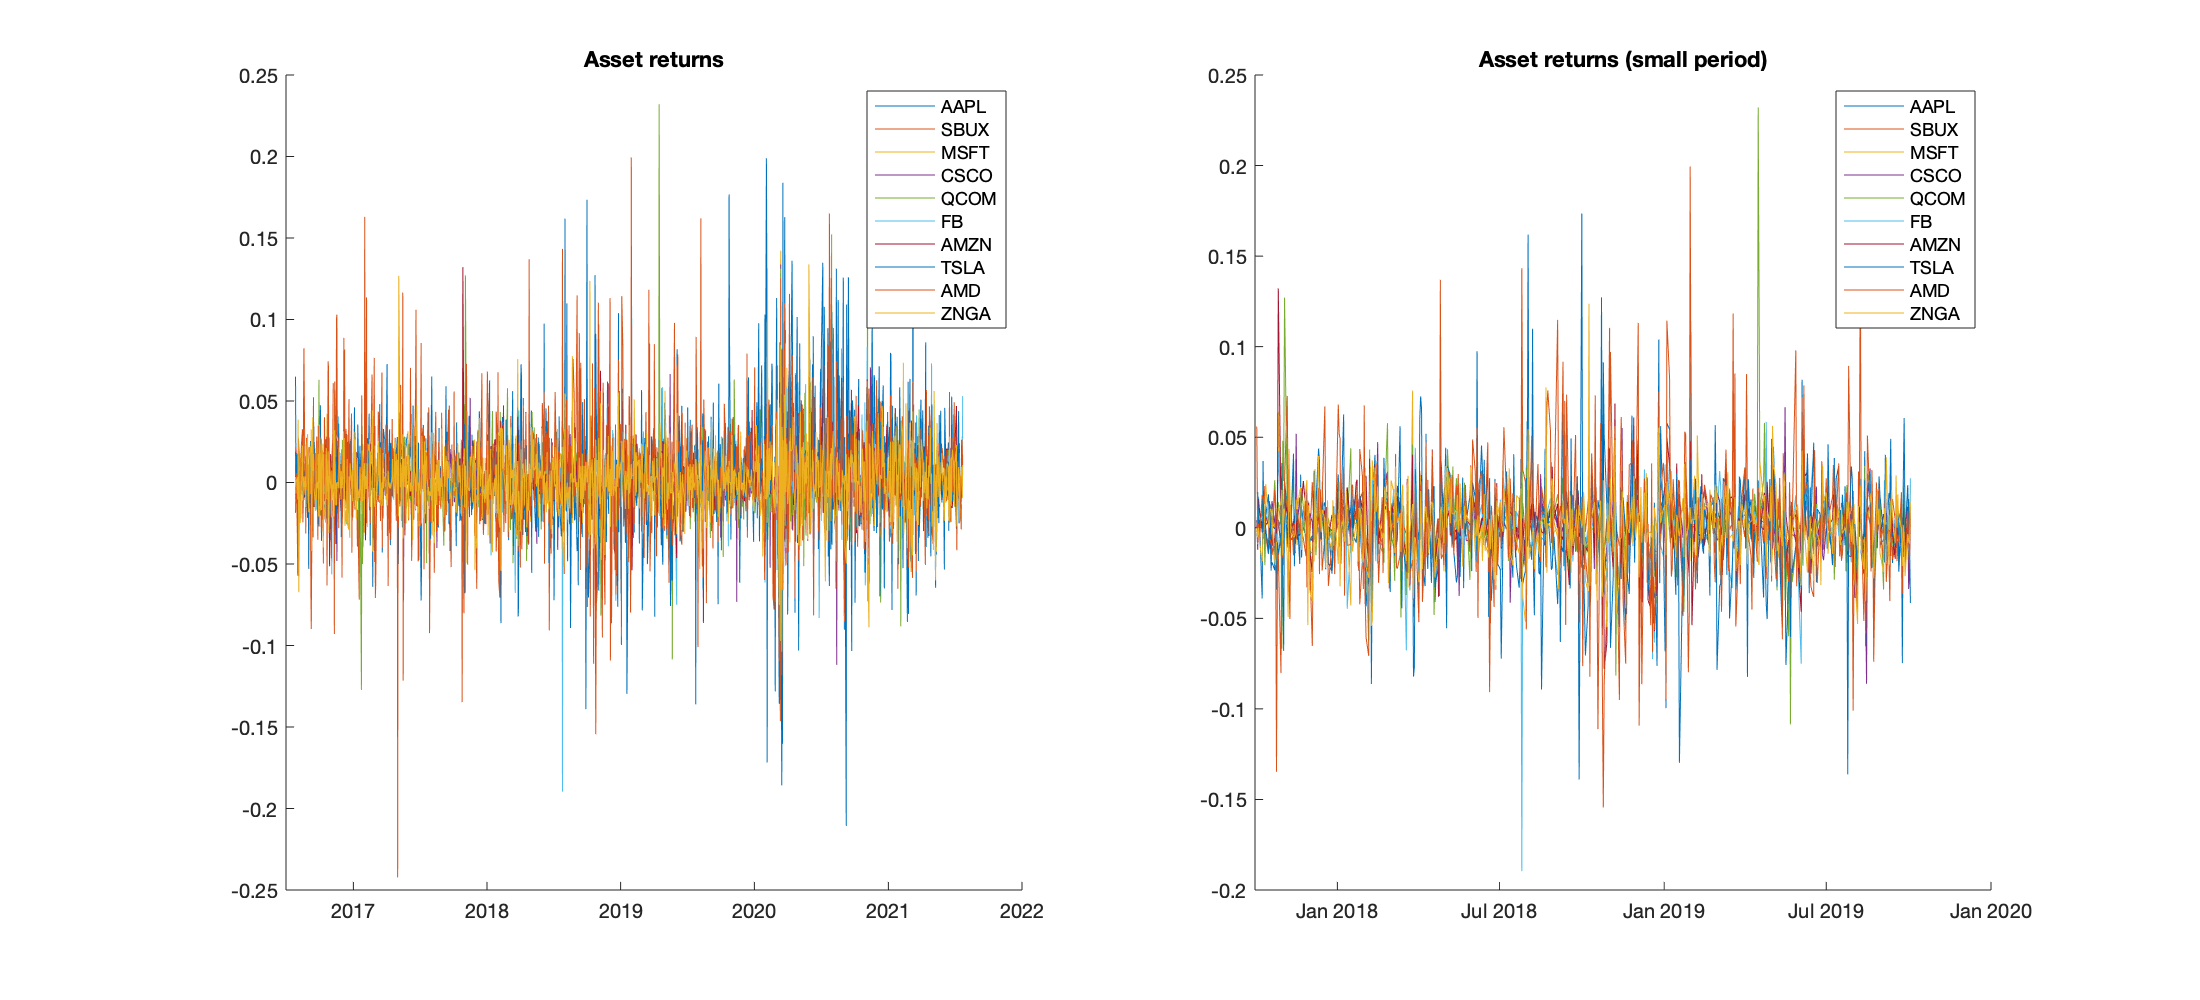

date = date(300:803);
returns = returns(:,300:803);
subplot(1, 2, 2)
for i = 1:num_asset
    hold on
    plot(date,returns(i,:))
end
title('Asset returns (small period)');
legend(list_stock);
hold off

 A questo punto, dopo aver importato i dati, siamo in grado di calcolare la media e la matrice di varianza-covarianza VERE tra i diversi stock, andando ad utilizzare questi dati possiamo calcolare i pesi ***veri*** del portafoglio a media varianza ottimo che poi andremo a confrontare con il portafoglio che si ottiene dopo la stima dei parametri. Un ultimo ingrediente necessario per calcolare un portafoglio a media varianza, è il *coefficiente di avversione al rischio *che indichiamo con *lamdba*, infatti, mentre la Capital Allocation Line definisce l’universo dei portafogli ammissibili, è proprio questo coefficiente che ci dà informazioni relative alla posizione lungo la retta, nella quale fermarci, quindi quale portafoglio deve essere specificato. Nello specifico, valori ragionevoli di *lambda *sono quelli compresi nell’intervallo [2, 4], quindi almeno per il momento, utilizzeremo un coefficiente di avversione al rischio pari a 3. Tuttavia, al variare di *lambda* in [0, ∞] riusciamo a tracciare tutta la frontiera dei portafogli efficienti. Per calcolare il portafoglio ottimo, è necessario risolvere un problema di massimizzazione dove la funzione obiettivo è una sorta di funzione di utilità data da una combinazione lineare dei due scopi che vogliamo raggiungere (valore atteso del mio portafoglio più grande possibile e variabilità del portafoglio più bassa possibile) che però sono in contrasto. Quando l’unico vincolo che imponiamo sui pesi del portafoglio è che la loro somma sia pari ad 1 (e quindi richiediamo effettivamente che i *w* siano dei pesi), abbiamo a disposizione una formula chiusa per il calcolo dei pesi e possiamo quindi utilizzare la funzione *QuadFolio*. Dalla soluzione osserviamo che il portafoglio ottimo contiene alcuni pesi negativi (come ad esempio per l’asset della Apple o per quello di Facebok), questo vuol dire che stiamo assumendo che sia possibile fare vendita allo scoperto. Ovvero stiamo permettendo all’investitore di vendere un asset finanziario che non si possiede e poi ricomprarlo, cercando di venderlo ad un prezzo più alto di quello al quale verrà riacquistato in modo da generare un profitto.

trueMu = mean(returns,2);
trueSigma = cov(returns');
lambda = 3;
%Non impongo vincoli sulla vendita allo scoperto
[truewp,~,~] = QuadFolio(trueMu, trueSigma, lambda);

f3=figure

f3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 3.00
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [440.00 378.00 560.00 420.00]
       Units: 'pixels'

  Show all properties


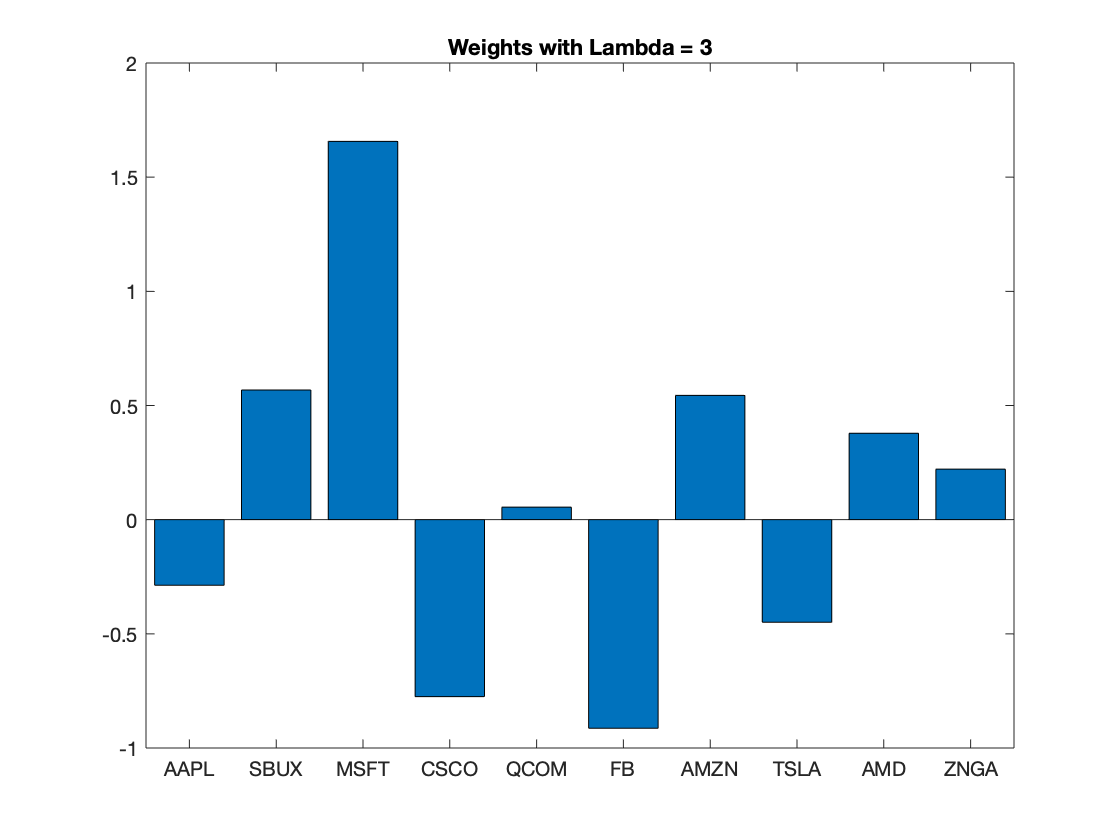

stockCat = categorical(list_stock);
stockCat = reordercats(stockCat,list_stock);
bar(stockCat,truewp)
title('Weights with Lambda = 3')

Weights = zeros(num_asset,3);
Weights(:,2) = truewp;

In alternativa, è possibile utilizzare la funzione *quadprog*, già implementata in Matlab che però non sfrutta la soluzione analitica, ma ci permetterebbe di risolvere il problema anche in presenza di vincoli lineari sulla composizione del portafoglio, compreso il vincolo che proibisce vendite allo scoperto. Verifichiamo innanzitutto che le due soluzioni relative ai singoli pesi coincidano nel caso in cui non ci siano ulteriori vincoli.

options = optimoptions('quadprog','Display','none');
x = quadprog(lambda*trueSigma,-trueMu,[],[],ones(1,num_asset),1,[],[],[],options);
%check stesso risultato
max(abs(truewp-x))<1.0e-4

ans = logical
   1


## **Impatto degli errori di stima sui pesi dei singoli asset**

Per capire quale sia l’impatto degli errori sulla stima del portafoglio ottimale, assumiamo di non conoscere il valore vero del vettore dei valori attesi e della matrice di covarianza da passare alla funzione *QuadFolio*.  Prima di chiamare la funzione, settiamo il seme per una questione di riproducibilità, quindi utilizziamo la funzione *estimated_portfolio *che fa mille replicazioni ciascuna estraendo un campione di 250 elementi, ad indicare un’analisi relativa all’anno precedente, da una distribuzione normale con media e matrice di covarianza quelle vere che abbiamo calcolato dai dati. Infine, la funzione restituisce, in questo caso, solamente i pesi del portafoglio ottimale che viene calcolato con la funzione *QuadFolio* a cui andiamo a passare il valore atteso e la matrice di covarianza campionarie (calcolate direttamente dai dati) e lo stesso coefficiente di avversione al rischio del caso precedente per poter confrontare i risultati. Ovviamente i valori stimati non saranno perfettamente uguali a quelli veri, ma dovrebbero avvicinarsi molto. Tuttavia, com’è possibile osservare dall’istogramma, ad esempio del peso del primo asset (stock Apple, che nel portafoglio ottimale ha un peso negativo) o del terzo asset (associato allo stock Microsoft, che nel portafoglio ottimale ha un peso positivo) c’è un’estrema variabilità nei pesi e ci allontaniamo anche di molto dal peso ottimale che si ottiene nel portafoglio con i parametri veri.

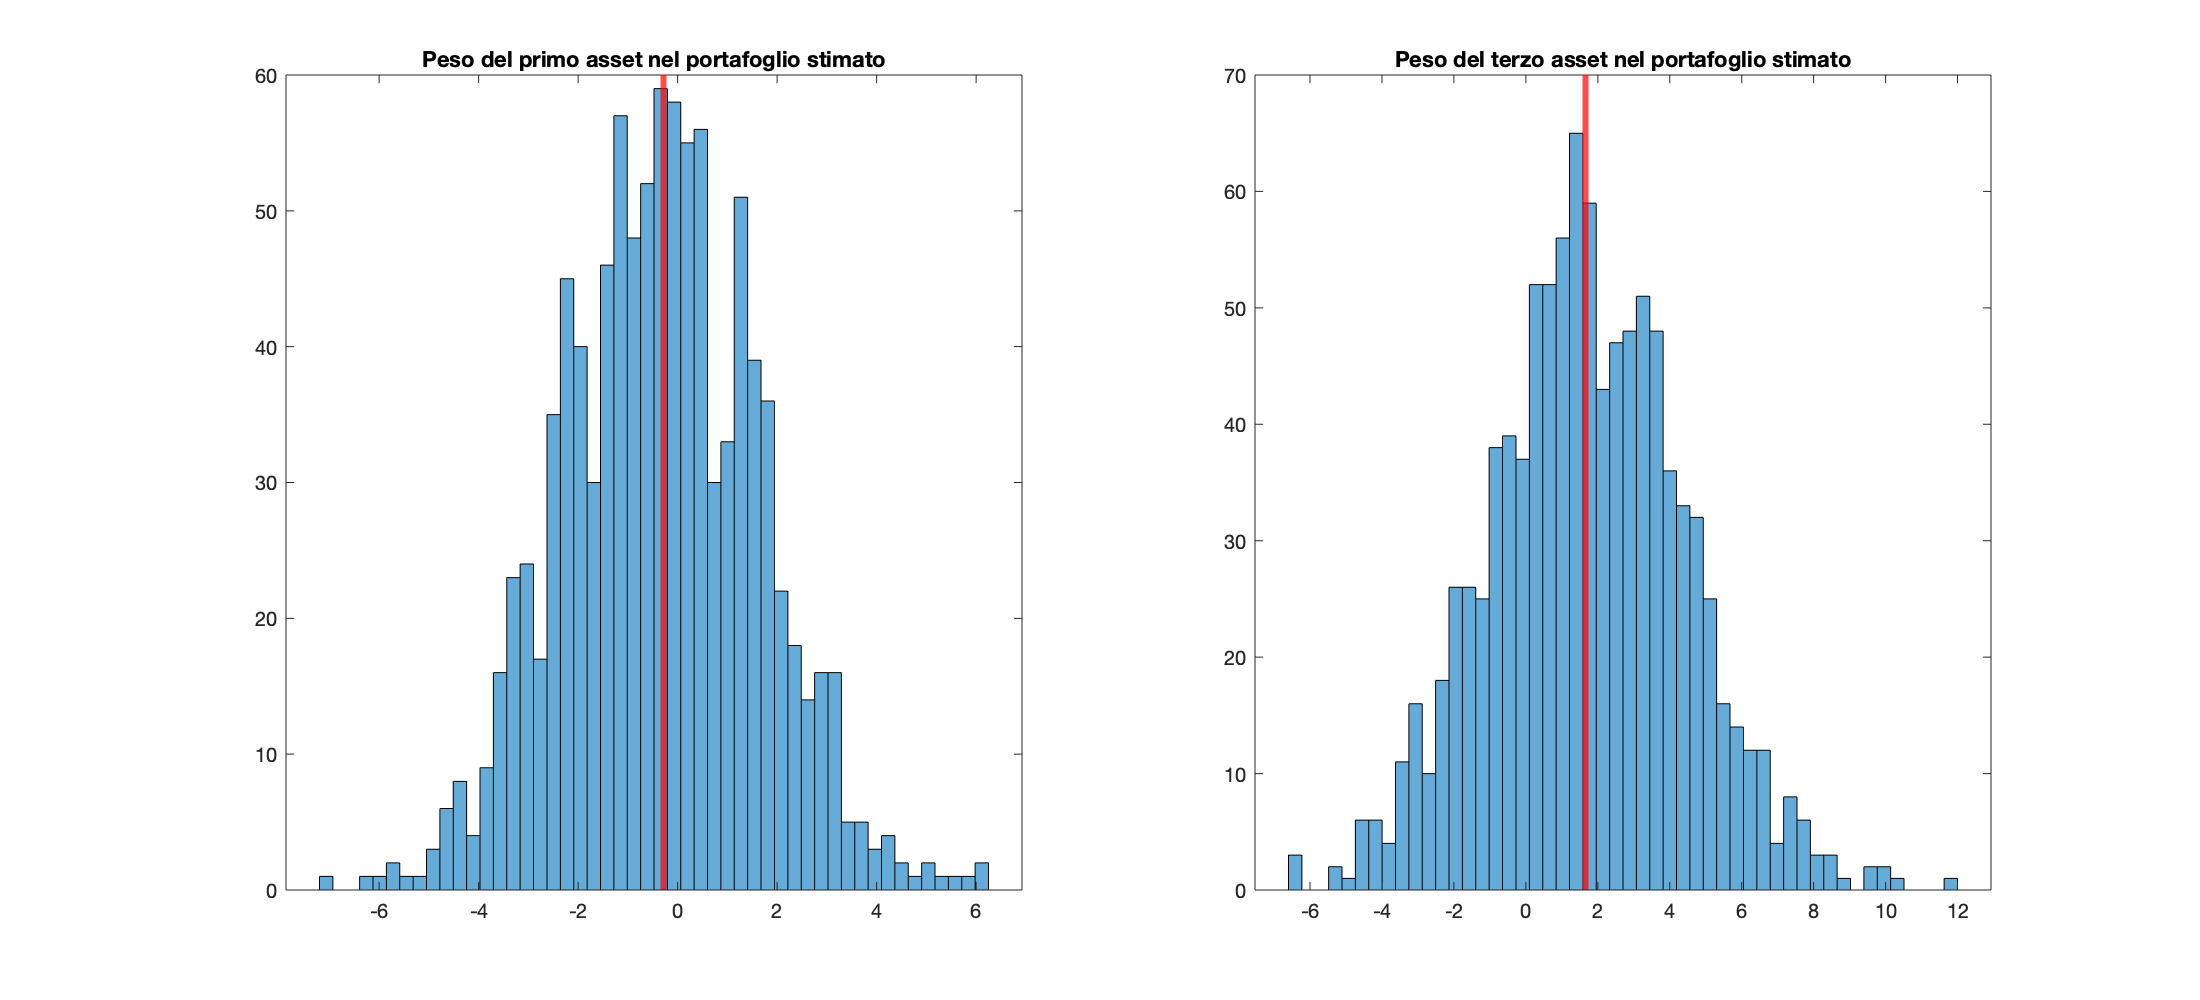

rng('default'); % ripetibilità
[~,w] = estimated_portfolio(1000, trueMu, trueSigma, lambda, 0, 'estimated', false, 250);
f2=figure('Position', [0, 50, 1100, 500]);
subplot(1,2,1)
histogram(w(:,1),50); %peso del primo asset nel portafoglio
xline(truewp(1),'r','LineWidth',3); %valore ottimo vero
title('Peso del primo asset nel portafoglio stimato');
subplot(1,2,2)
histogram(w(:,3),50); %peso del terzo asset nel portafoglio
xline(truewp(3),'r','LineWidth',3); %valore ottimo vero
title('Peso del terzo asset nel portafoglio stimato');

***Dimensione del campione***

Proviamo a vedere se la situazione migliora, andando a ripetere esattamente gli stessi passaggi del caso precedente, andando però questa volta, a passare un numero di campioni più alto, pari a 2500, per ogni replicazione, che corrispondono quindi a circa 10 anni di dati storici giornalieri. Per entrambi gli asset, osserviamo che la variabilità si riduce notevolmente, tuttavia non sempre avremo a disposizione un numero così elevato di dati per poter campionare da una distribuzione normale, quindi sicuramente il caso precedente risulta più realistico.

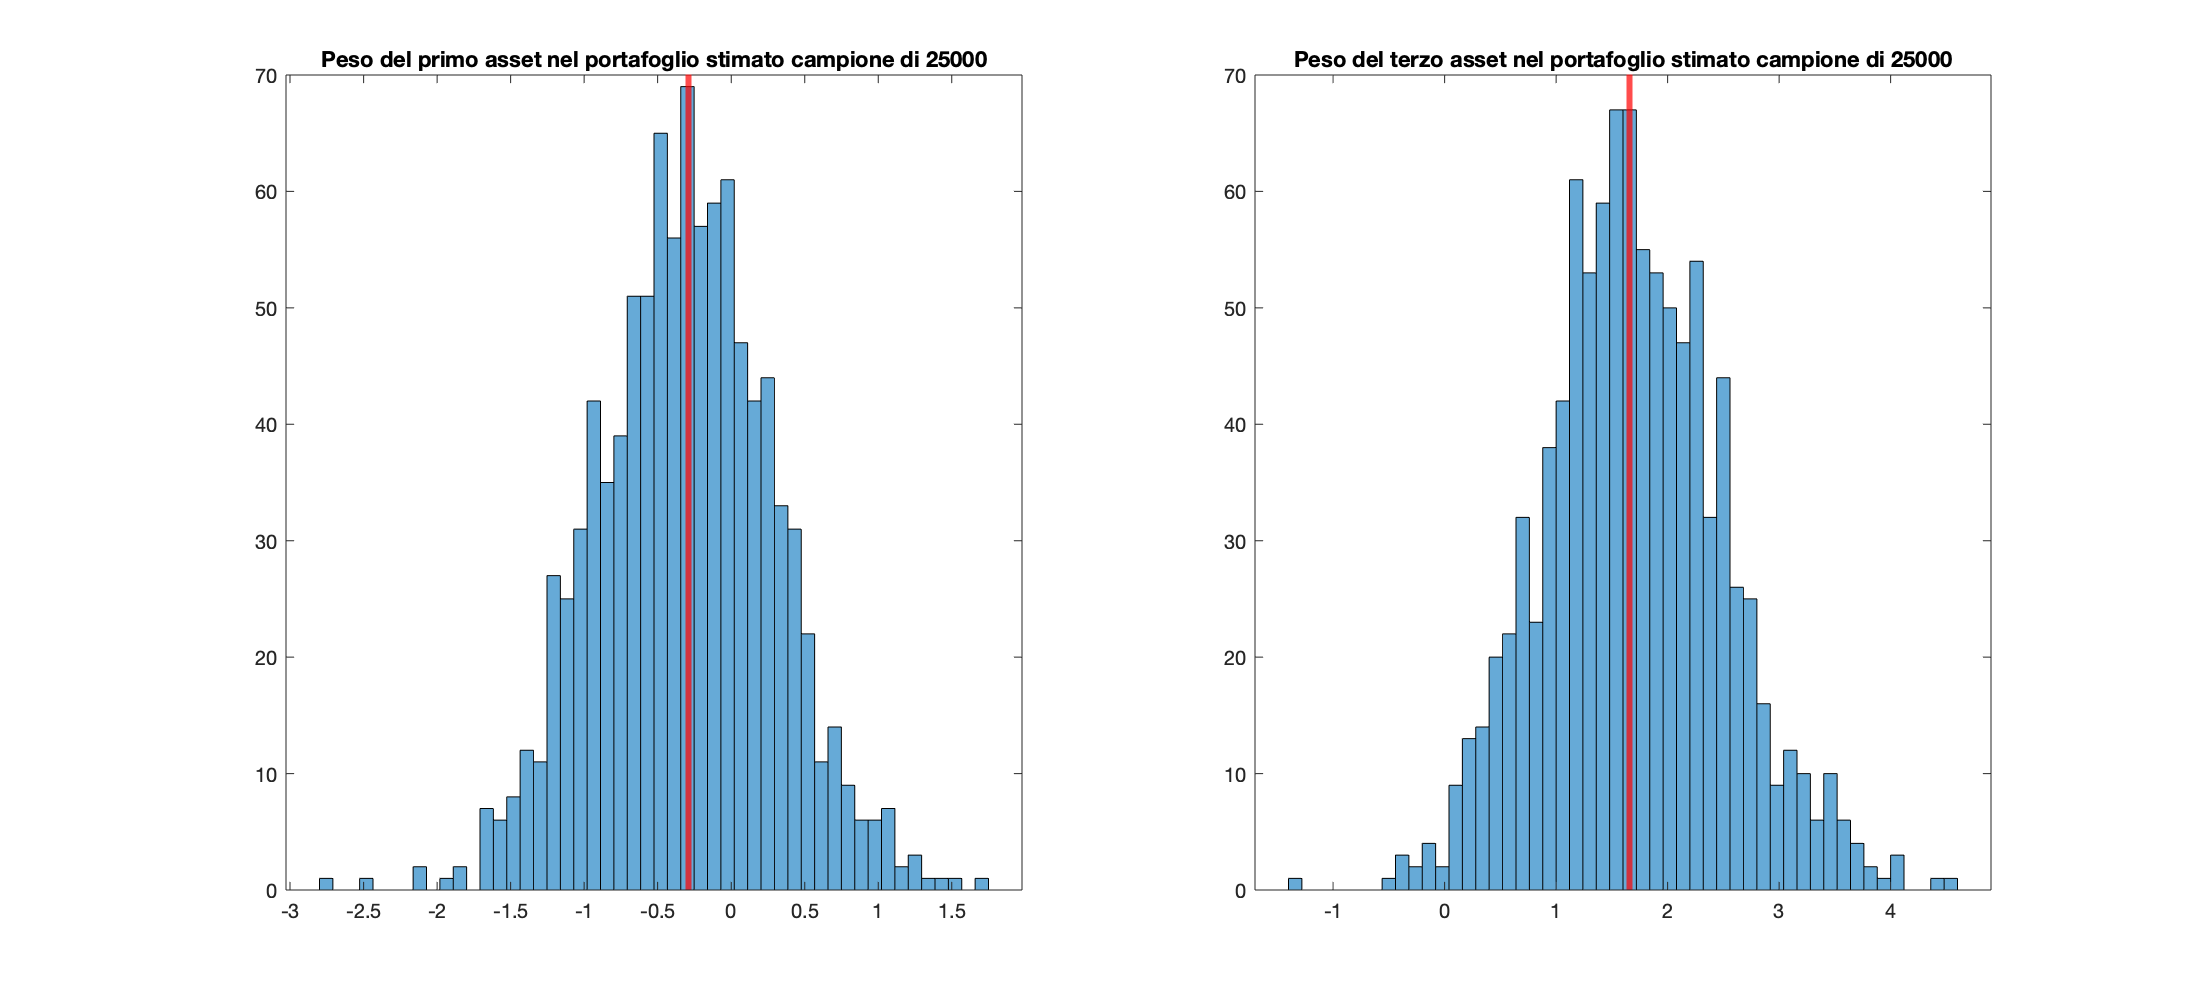

rng('default'); % ripetibilità
[~,w1] = estimated_portfolio(1000, trueMu, trueSigma, lambda, 0, 'estimated', false, 2500);
f=figure('Position',[0, 0, 1100, 500]);
subplot(1, 2, 1)
histogram(w1(:, 1),50);
xline(truewp(1),'r','LineWidth',3);
title('Peso del primo asset nel portafoglio stimato campione di 25000')
subplot(1, 2, 2)
histogram(w1(:, 3),50);
xline(truewp(3),'r','LineWidth',3);
title('Peso del terzo asset nel portafoglio stimato campione di 25000')

***Coefficiente di avversione al rischio***

Un altro parametro che potrebbe migliorare la situazione relativa all’estrema variabilità dei pesi nel nostro portafoglio è il coefficiente di avversione al rischio. Infatti, è possibile andare a penalizzare maggiormente nella funzione obiettivo la variabilità del nostro portafoglio con un coefficiente di avversione più alto. In questo caso otterremo dei valori dei pesi molto più vicini al peso ottimale che si ottiene con i valori veri di Mu e Sigma, come è possibile osservare nella seconda figura. Infine, nell’ultima figura è possibile confrontare immediatamente i pesi per ciascun asset, che si ottengono al variare del coefficiente di avversione al rischio.

**(CHE SI PUO’ CONCLUDERE??)**

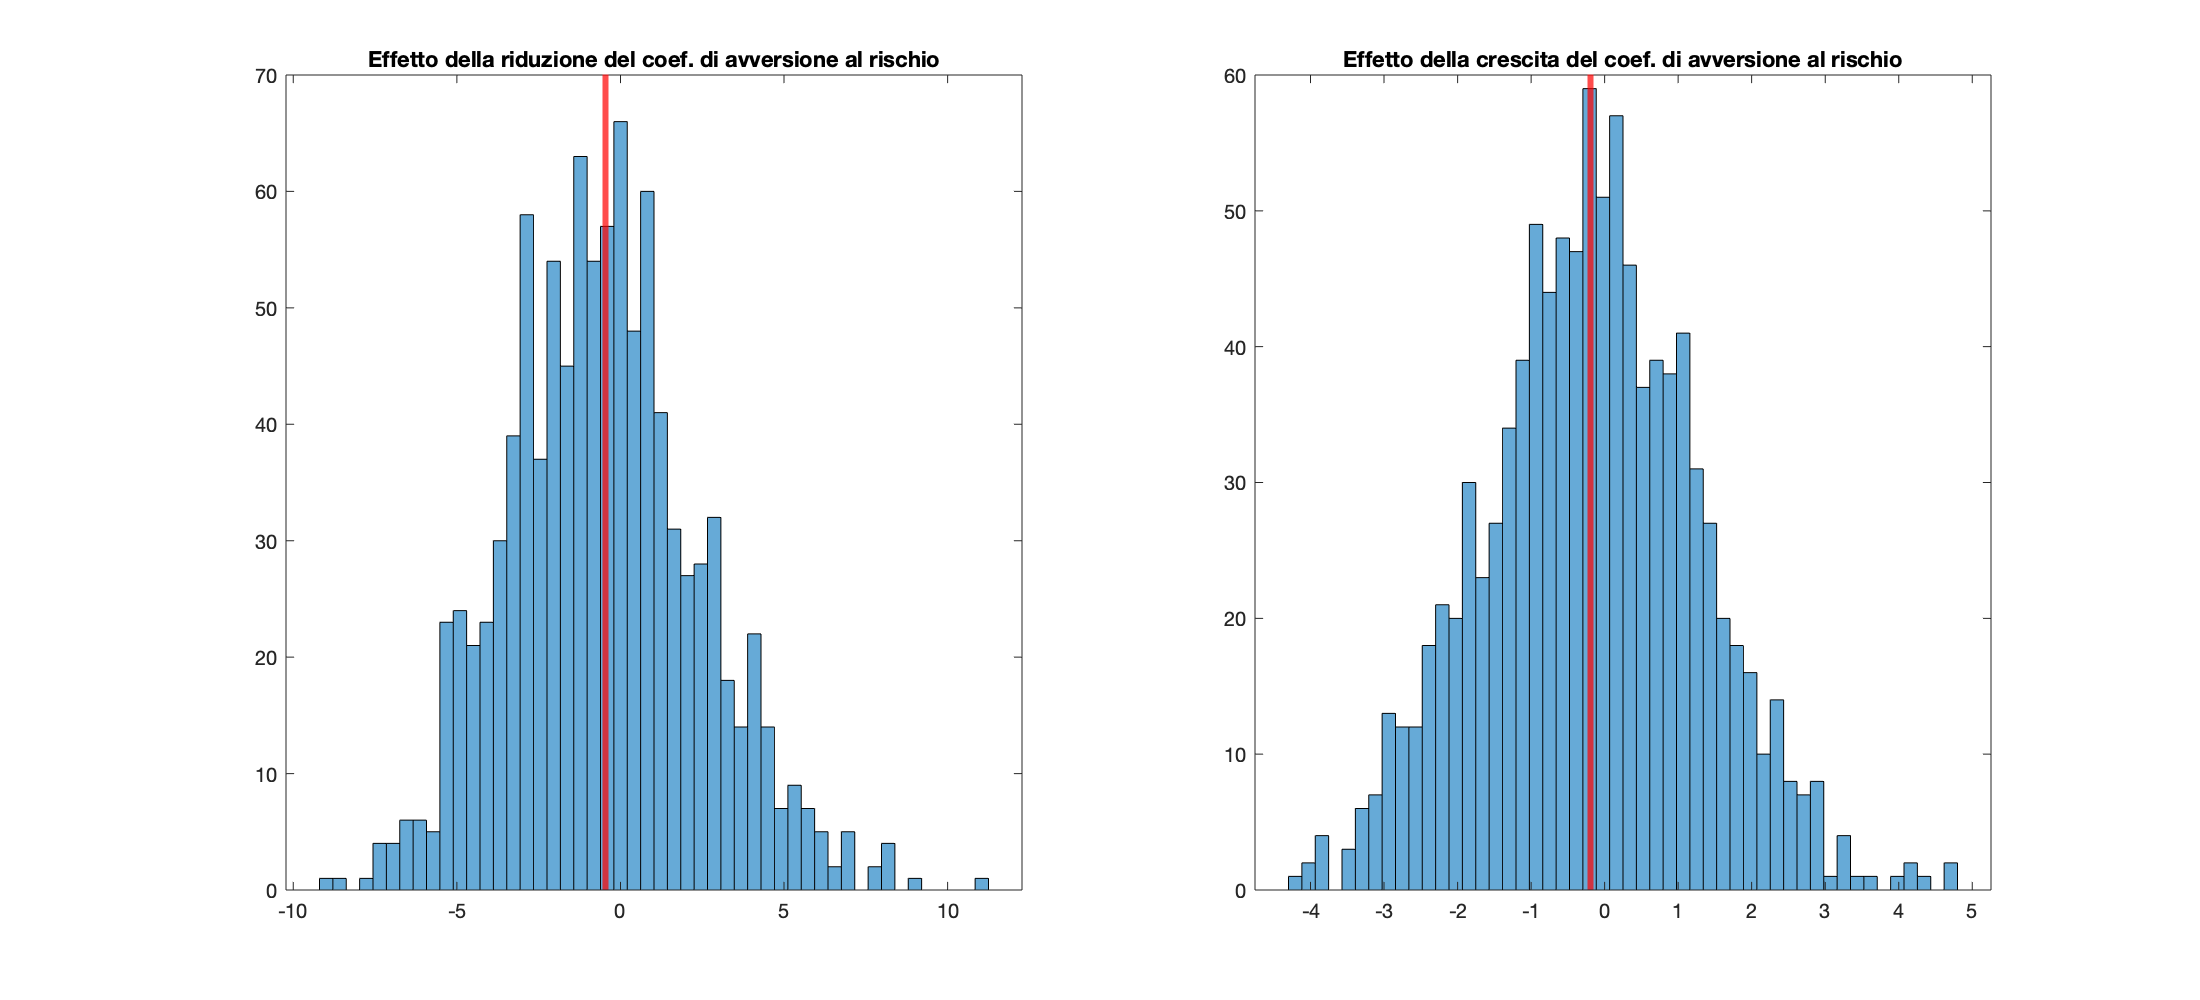

lambda2=2;
[truewp,~,~] = QuadFolio(trueMu, trueSigma, lambda2);
Weights(:,1) = truewp;
[~,w_lambda]=estimated_portfolio(1000, trueMu, trueSigma, lambda2, 0, 'estimated', false, 250);
f=figure('Position',[0, 0, 1100, 500]);
subplot(1, 2, 1)
histogram(w_lambda(:,1),50); %peso del primo asset nel portafoglio
xline(truewp(1),'r','LineWidth',3); %valore ottimo vero
title('Effetto della riduzione del coef. di avversione al rischio');

lambda3=4;
[truewp,~,~] = QuadFolio(trueMu, trueSigma, lambda3);
Weights(:,3) = truewp;
[~,w_lambda]=estimated_portfolio(1000, trueMu, trueSigma, lambda3, 0, 'estimated', false, 250);
subplot(1, 2, 2)
histogram(w_lambda(:,1),50); %peso del primo asset nel portafoglio
xline(truewp(1),'r','LineWidth',3); %valore ottimo vero
title('Effetto della crescita del coef. di avversione al rischio');

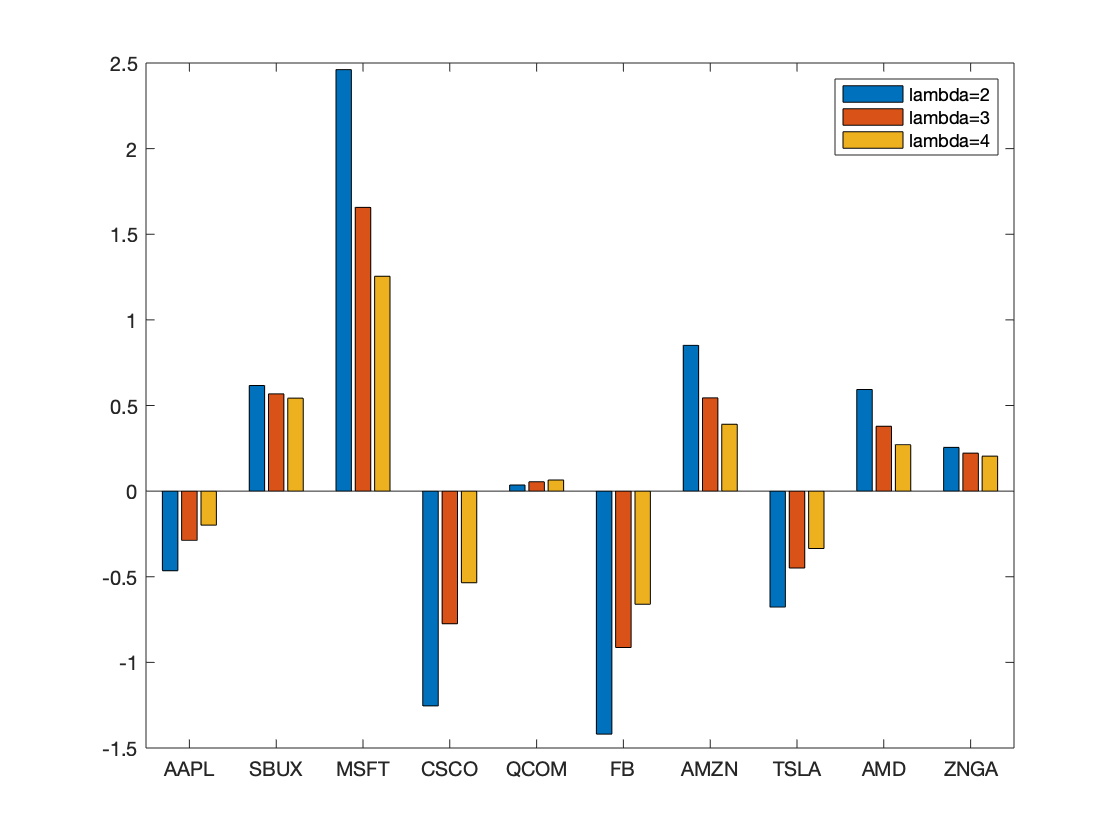

f=figure;
bar(stockCat,Weights)
legend('lambda=2', 'lambda=3', 'lambda=4');

***Vincolo sulla vendita allo scoperto***

Come già anticipato precedentemente, assumere che sia possibile fare vendita allo scoperto potrebbe essere abbastanza irrealistico e sarebbe opportuno imporre l’ulteriore vincolo che tutti i pesi debbano essere non negativi. Per risolvere il problema di ottimizzazione andremo ad utilizzare nuovamente la funzione *estimated_portfolio *scegliendo questa volta l'ottimizzazione per *'optimalNoShort'* per vedere cosa accade quando è presente questo ulteriore vincolo. Il portafoglio ottimo in questo caso è concentrato solamente su tre asset ed i loro pesi ovviamente sono positivi.

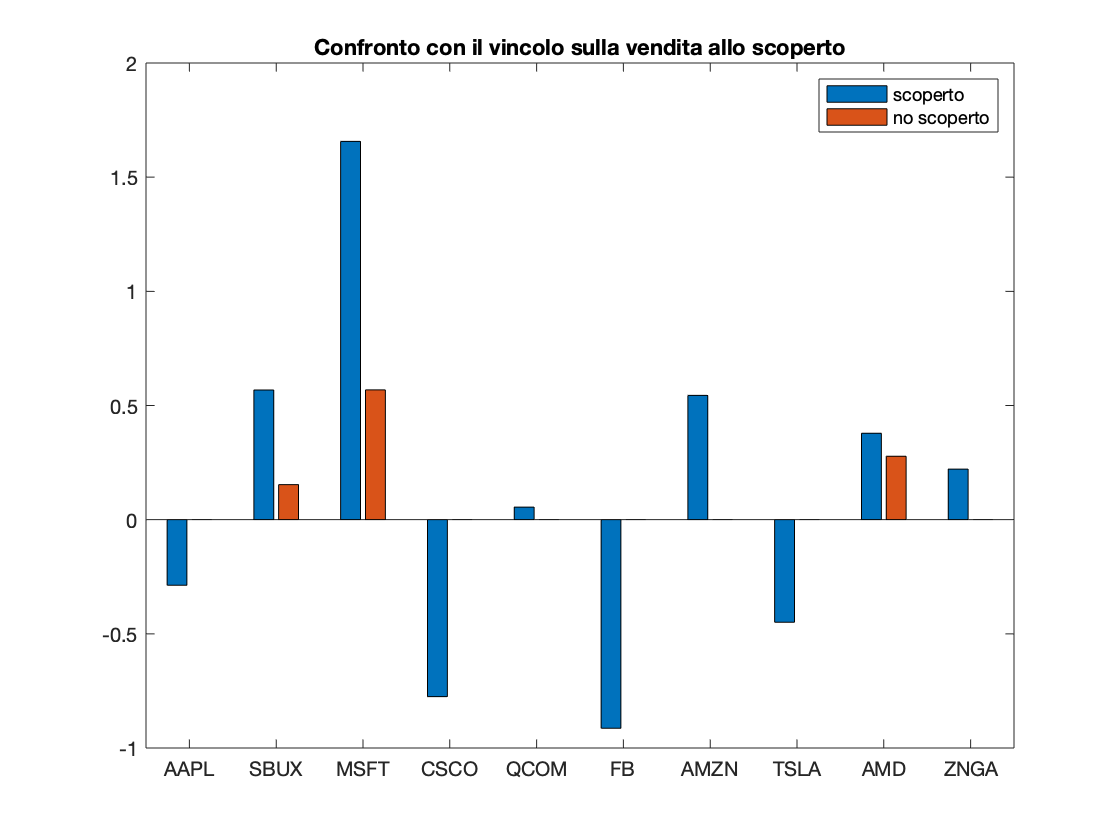

rng('default');
[~,x_no_scoperto] = estimated_portfolio(1, trueMu, trueSigma, lambda, 0, 'optimalNoShort', false, 0);
v=zeros(10, 2);
v(:,1)=Weights(:, 2);
v(:, 2)=x_no_scoperto;
bar(stockCat,v)
title('Confronto con il vincolo sulla vendita allo scoperto');
legend('scoperto', 'no scoperto');

***Portafoglio di minima varianza***

Una possibile alternativa al portafoglio a media-varianza è considerare il portafoglio di minima varianza, quindi non facendo entrare in gioco il vettore dei rendimenti attesi. Nella pratica questo portafoglio può essere visto anche come il limite di un portafoglio a media-varianza, dove però il coefficiente di avversione al rischio tende ad infinito.

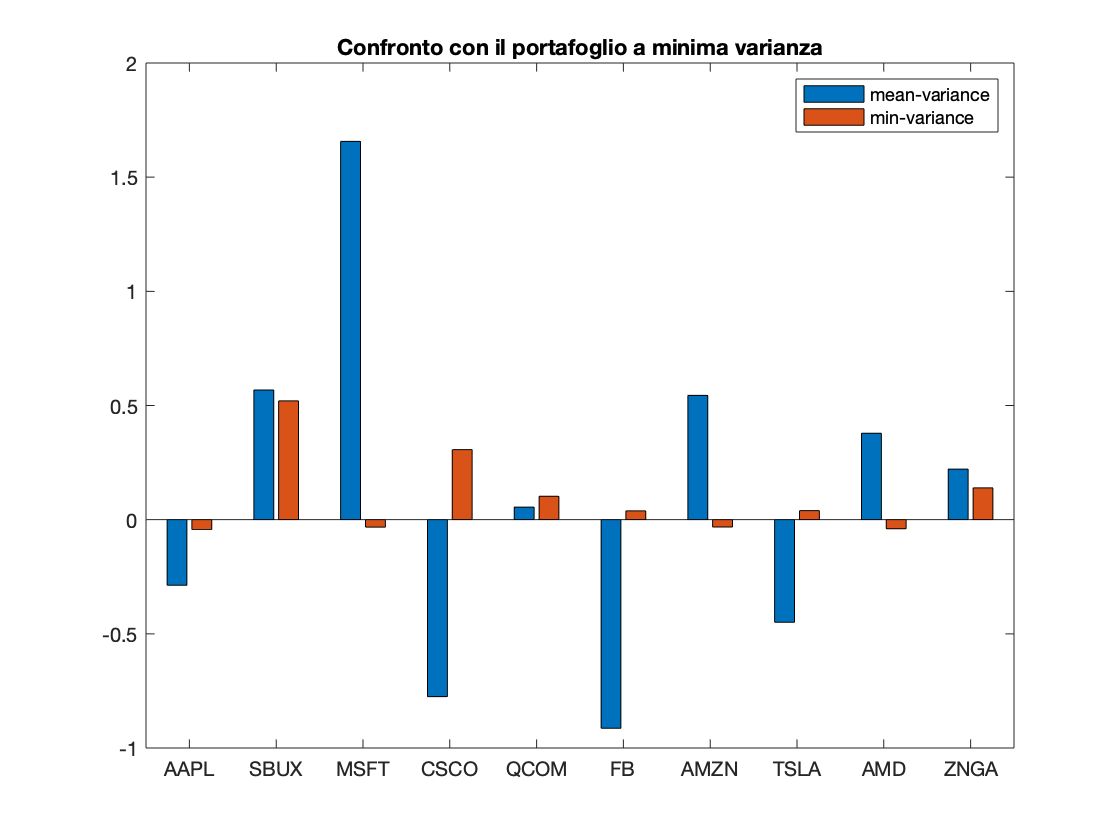

rng('default'); % ripetibilità
[~,xmv] = estimated_portfolio(1, trueMu, trueSigma, lambda, 0, 'minvariance', false, 250);
%figure
v=zeros(10, 2);
v(:,1)=Weights(:, 2);
v(:, 2)=xmv;
bar(stockCat,v)
title('Confronto con il portafoglio a minima varianza')
legend('mean-variance', 'min-variance')

***Portafoglio naive***

Una ulteriore alternativa possibile  è il portafoglio naive, dove la ricchezza iniziale viene divisa equamente tra i diversi asset. Questa strategia potrebbe sembrare molto semplice e banale, ma non è detto che sia necessariamente sbagliata. Infatti il vantaggio in questo caso è che non stiamo facendo nessuna assunzione relativamente alla distribuzione seguita dagli scenari, semplicemente scegliamo i pesi in base al numero di asset che abbiamo a disposizione e che vogliamo includere nel portafoglio.

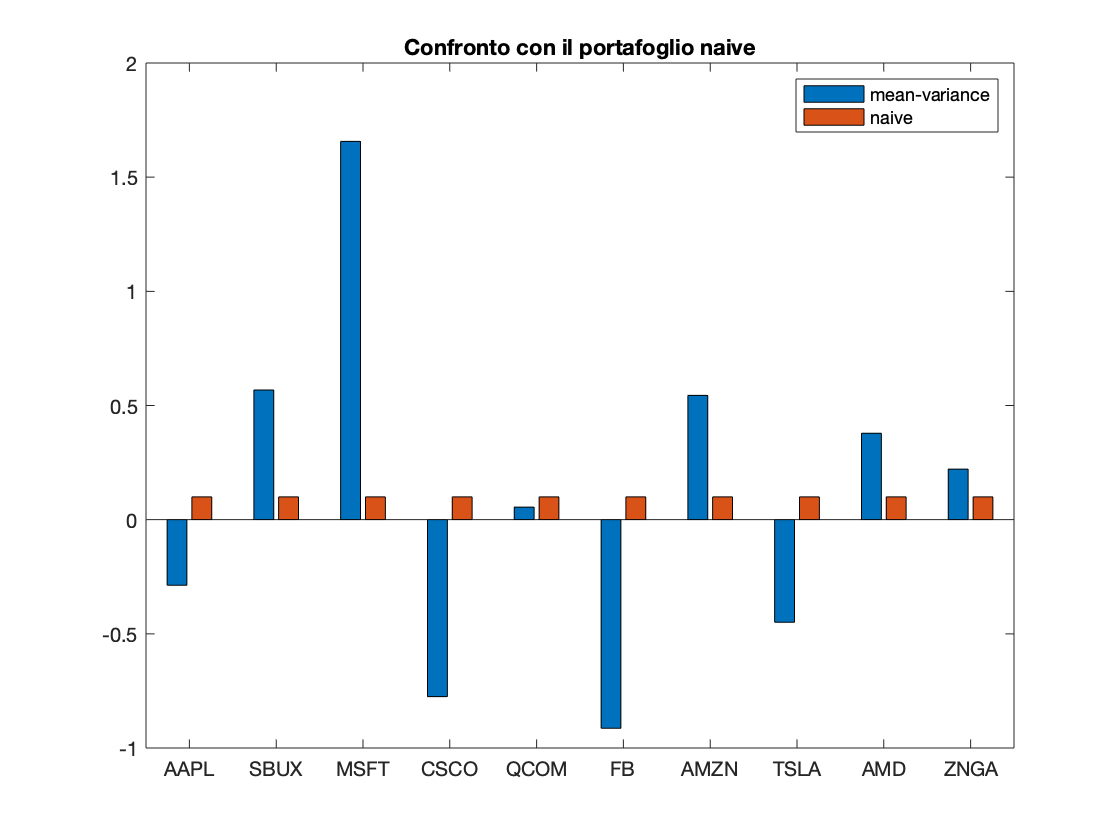

w_naive=1/length(trueMu)*ones(length(trueMu), 1);
%figure
v=zeros(10, 2);
v(:,1)=Weights(:, 2);
v(:, 2)=w_naive;
bar(stockCat,v)
title('Confronto con il portafoglio naive')
legend('mean-variance', 'naive')

## **Impatto degli errori di stima sui rendimenti**

A questo punto, per ciascuno dei portafogli introdotti precedentemente, andiamo a calcolare i rendimenti per vedere come entrano gli errori di stima nella scelta del portafoglio ottimo quando non abbiamo a disposizione i dati reali. Dai seguenti grafici, è possibile osservare che **(MANCA)**

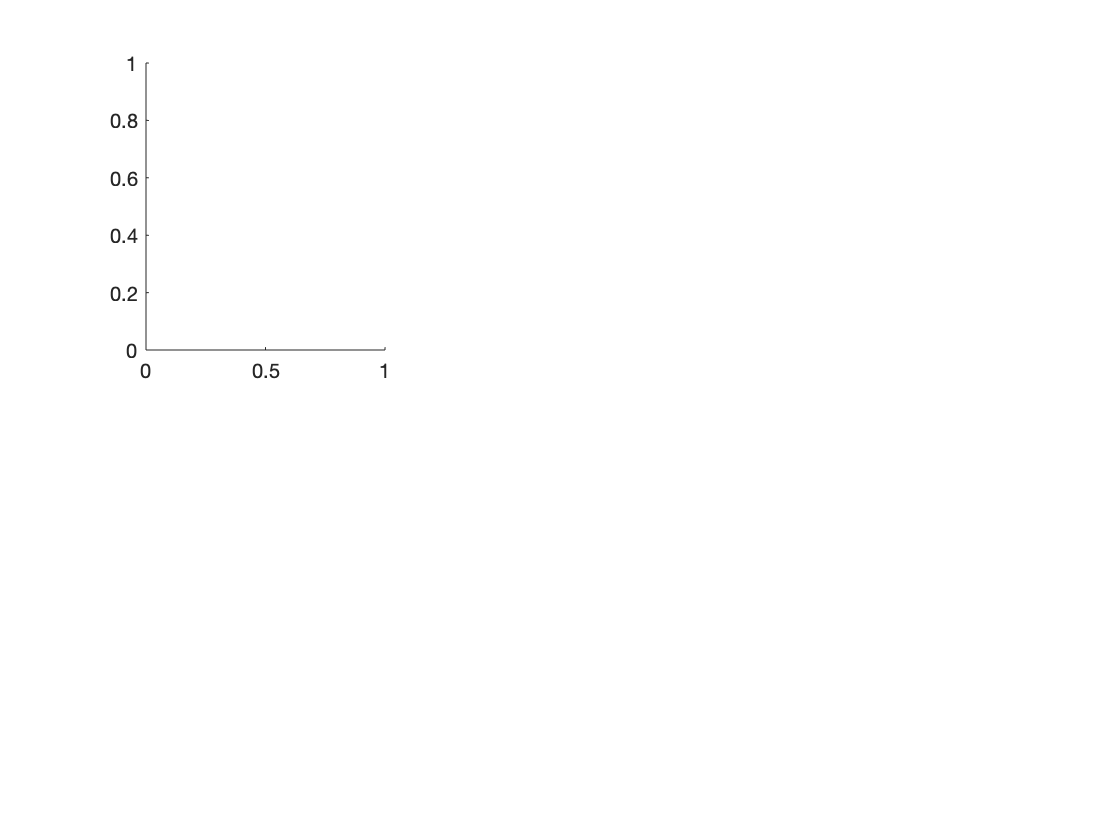

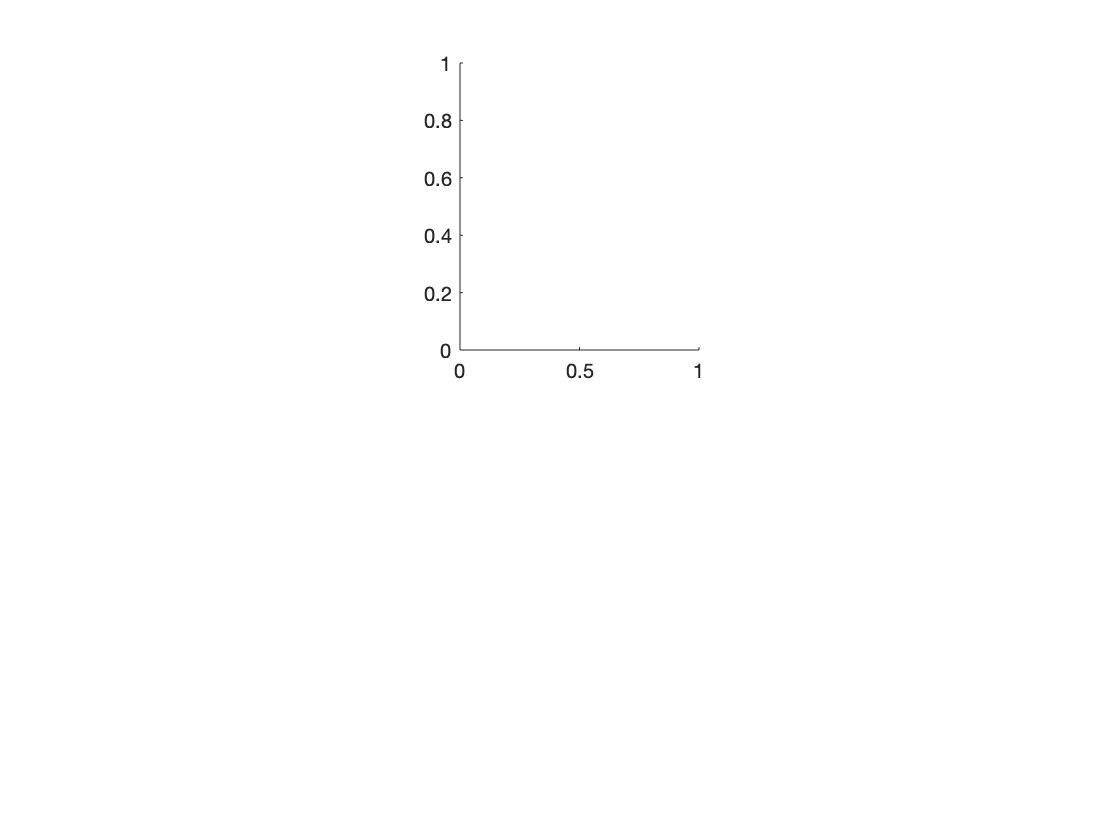

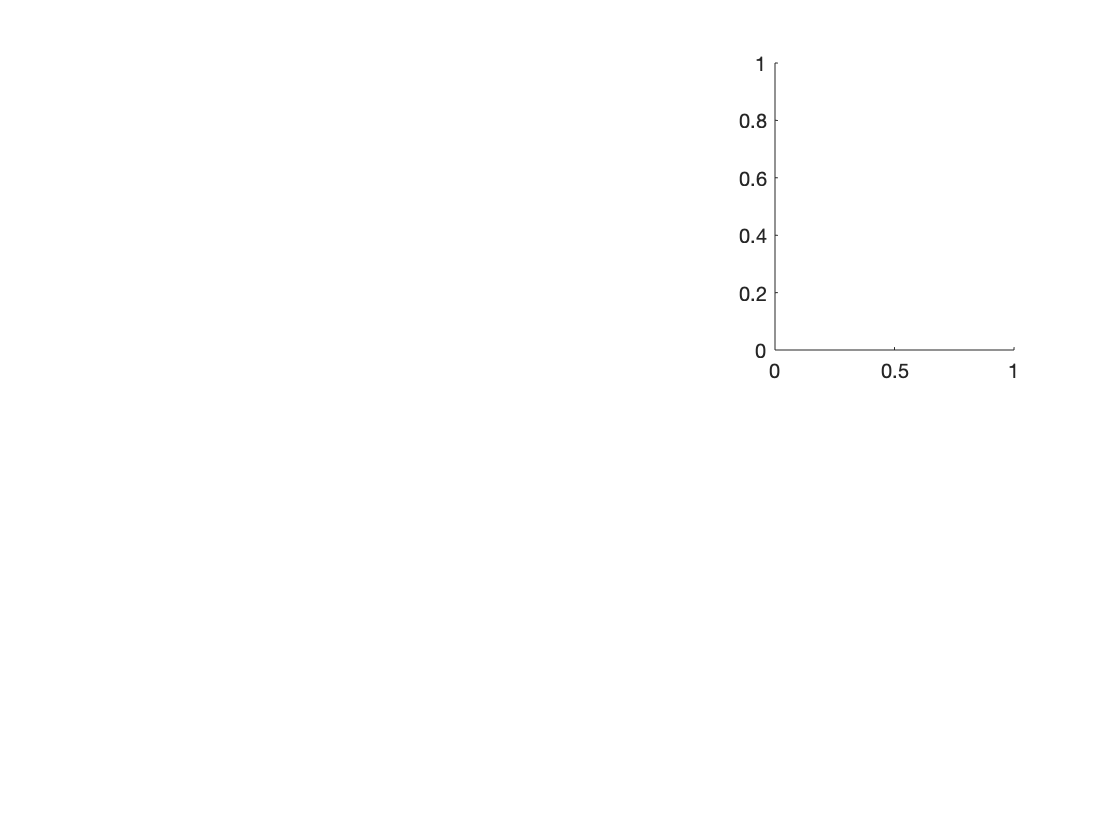

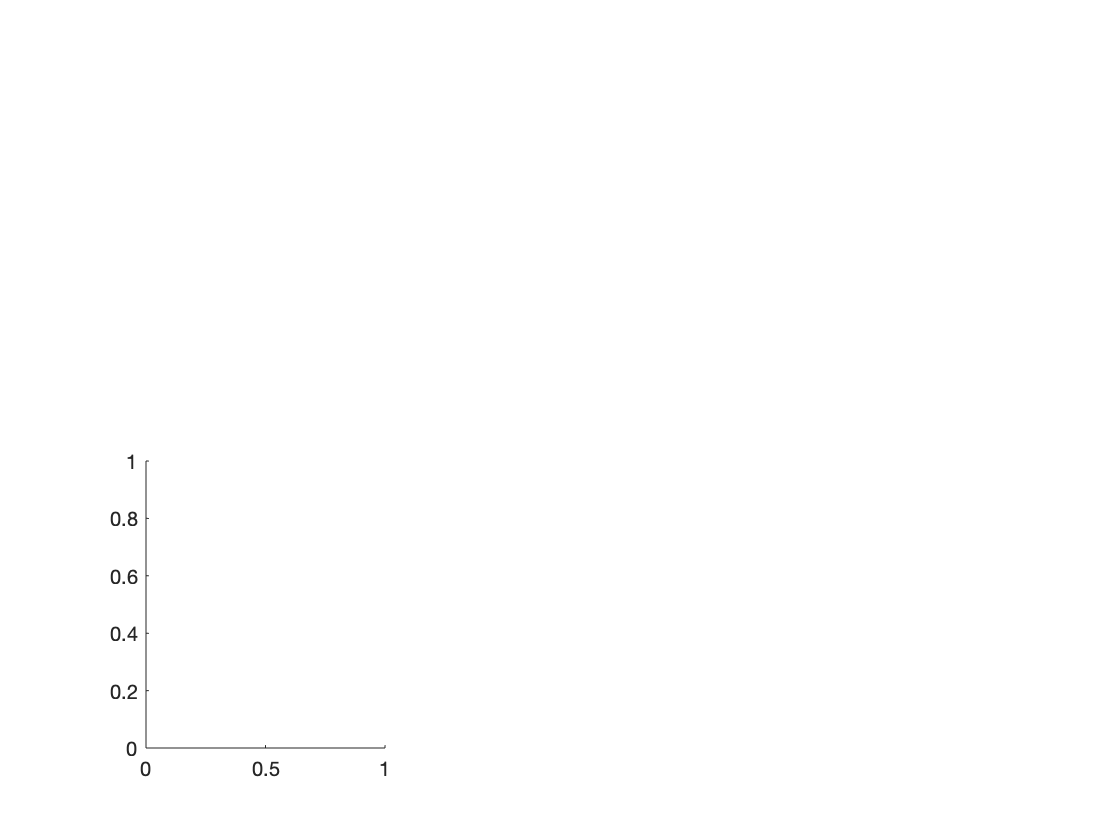

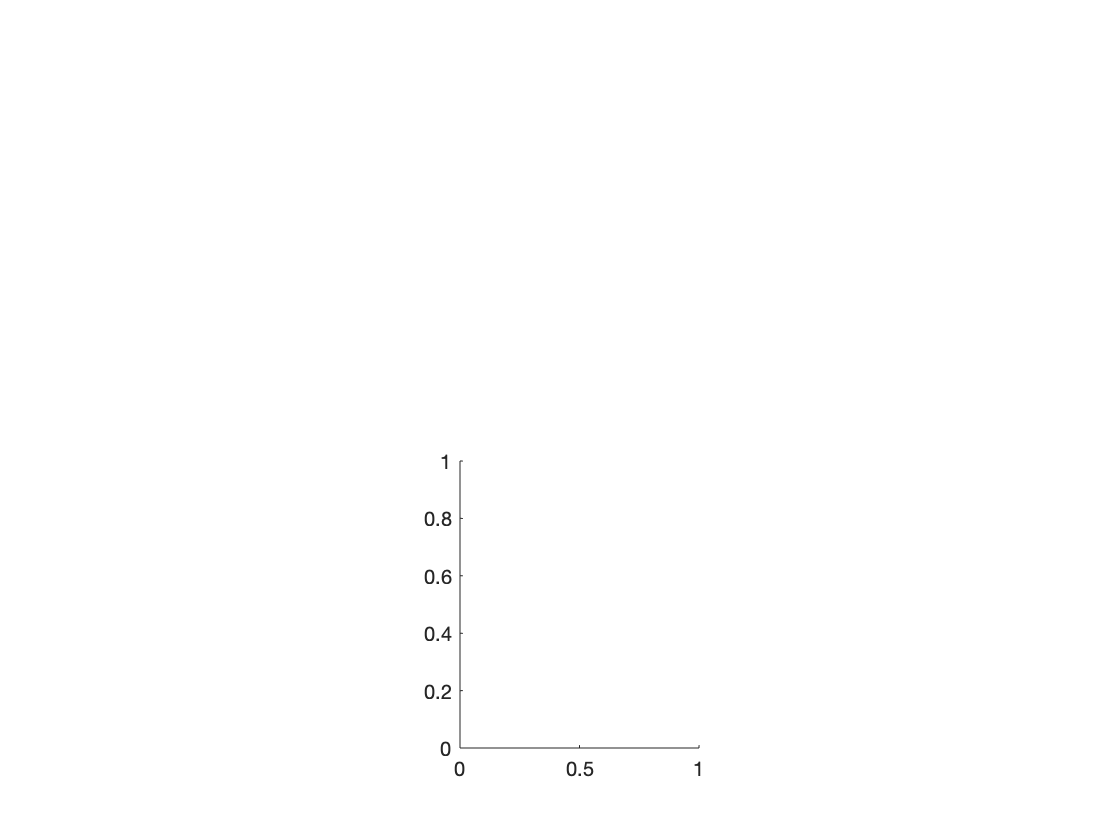

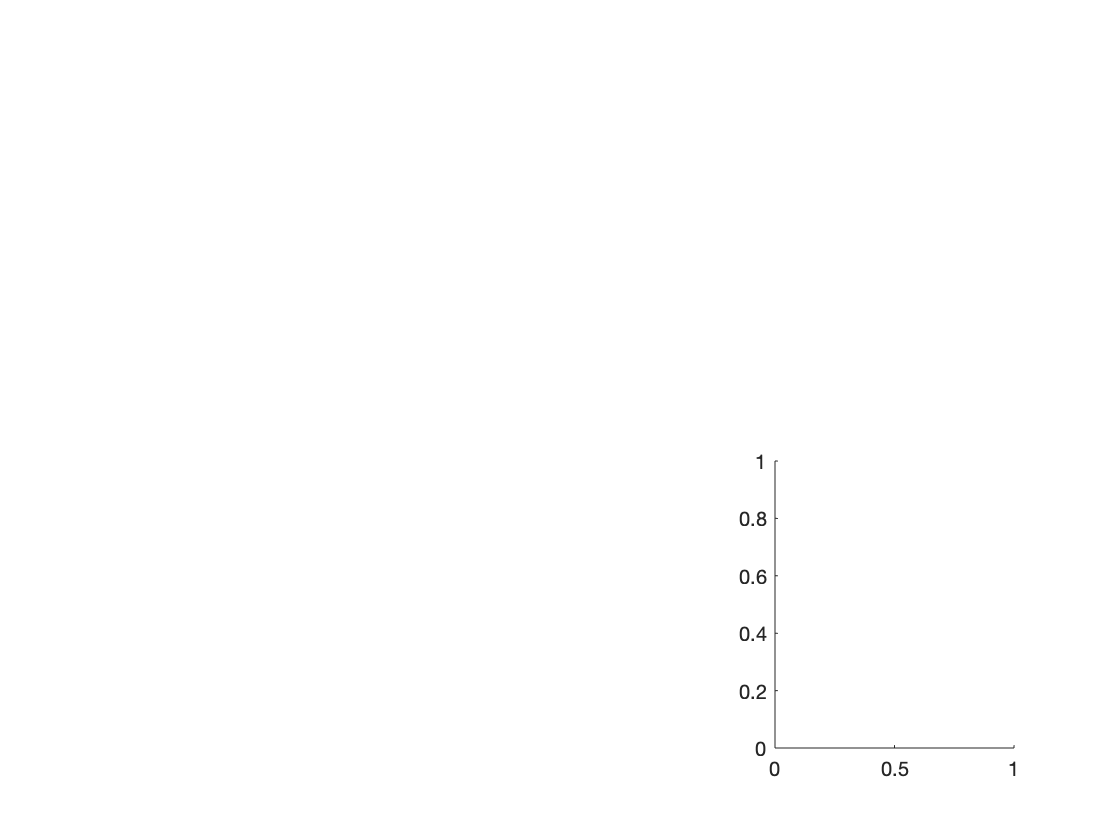

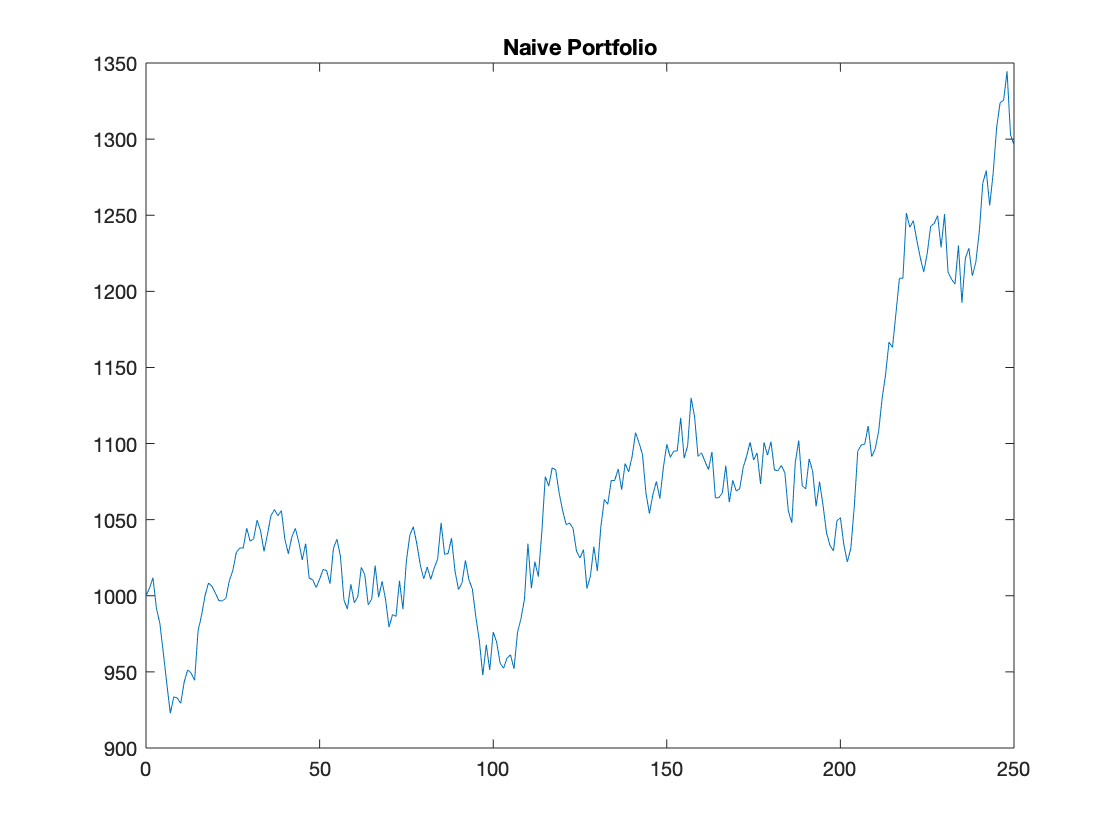

rng(2020); % ripetibilità
numRepl = 1;
plotWealth = true;
num_days = 250;
numPastDays = 250;
types = ["optimal","optimalNoShort","estimated","estimatedNoShort","minvariance","naive"];
f6=figure;
for type = 1:length(types)
    subplot(2, 3,type)
    estimated_portfolio(numRepl, trueMu, trueSigma, lambda, num_days, types(type), plotWealth, numPastDays);   
end

## **Stima rendimenti con aggiornamento pesi ogni settimana**

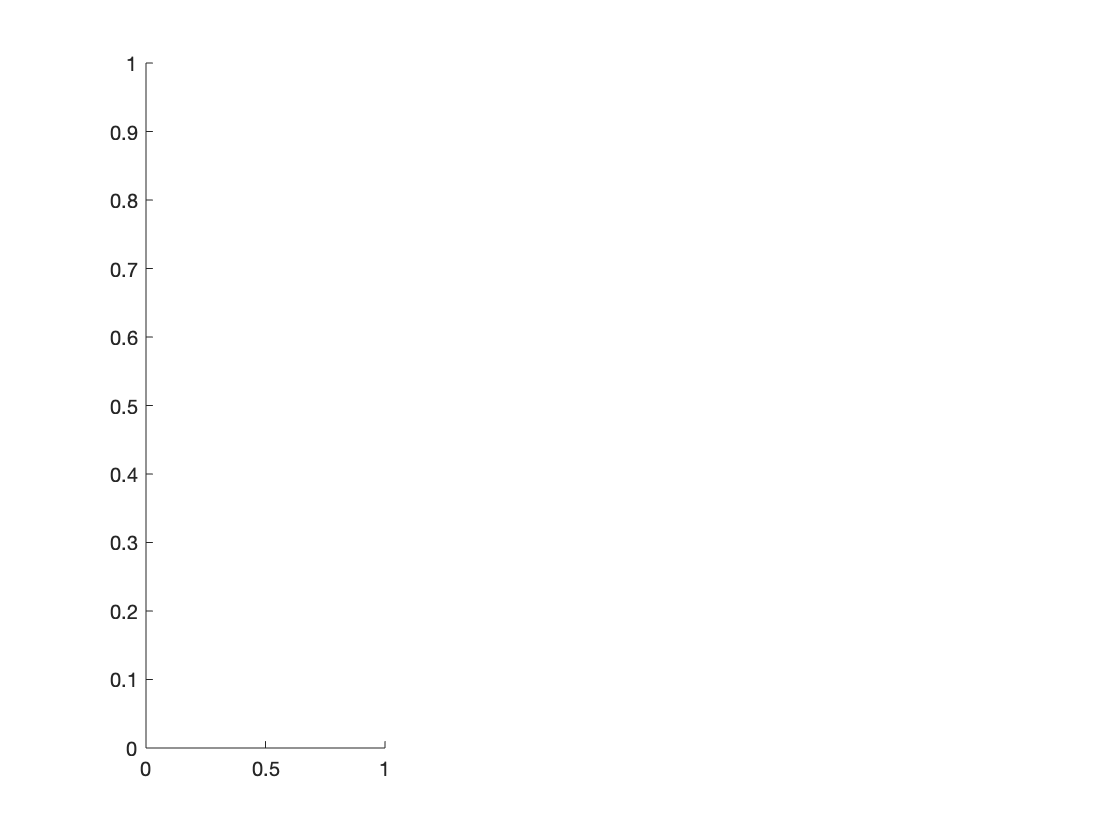

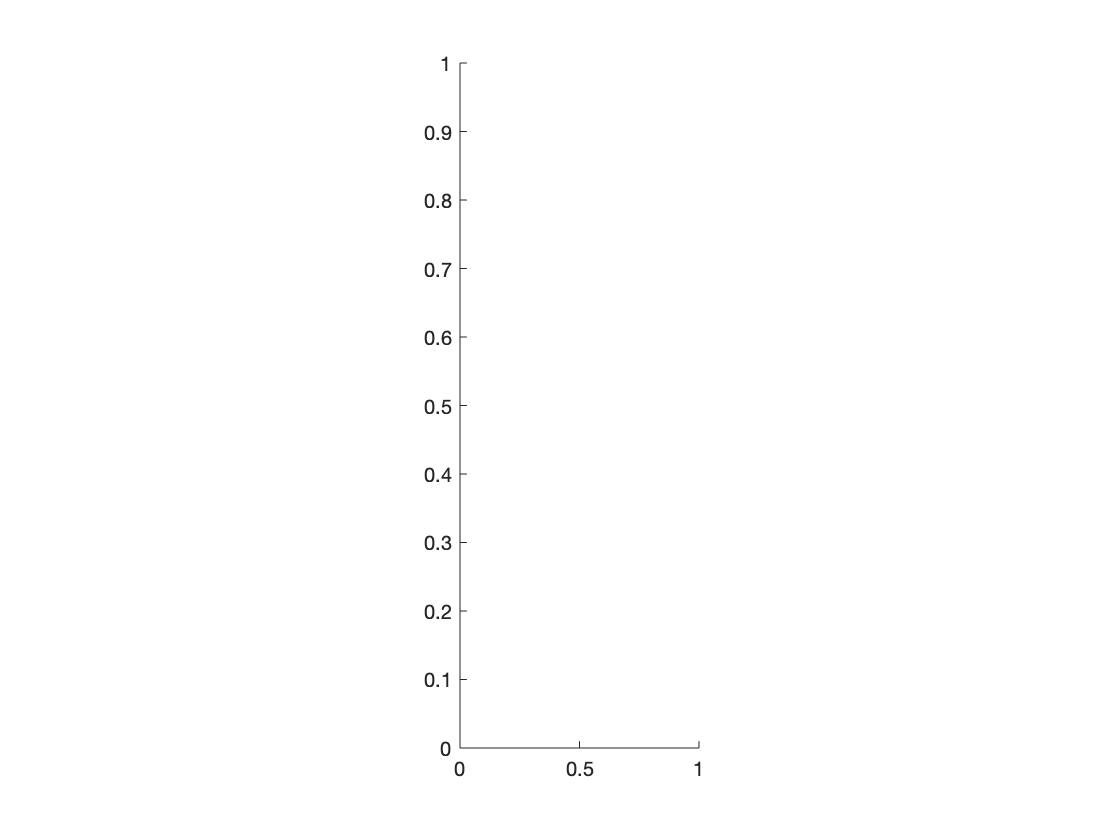

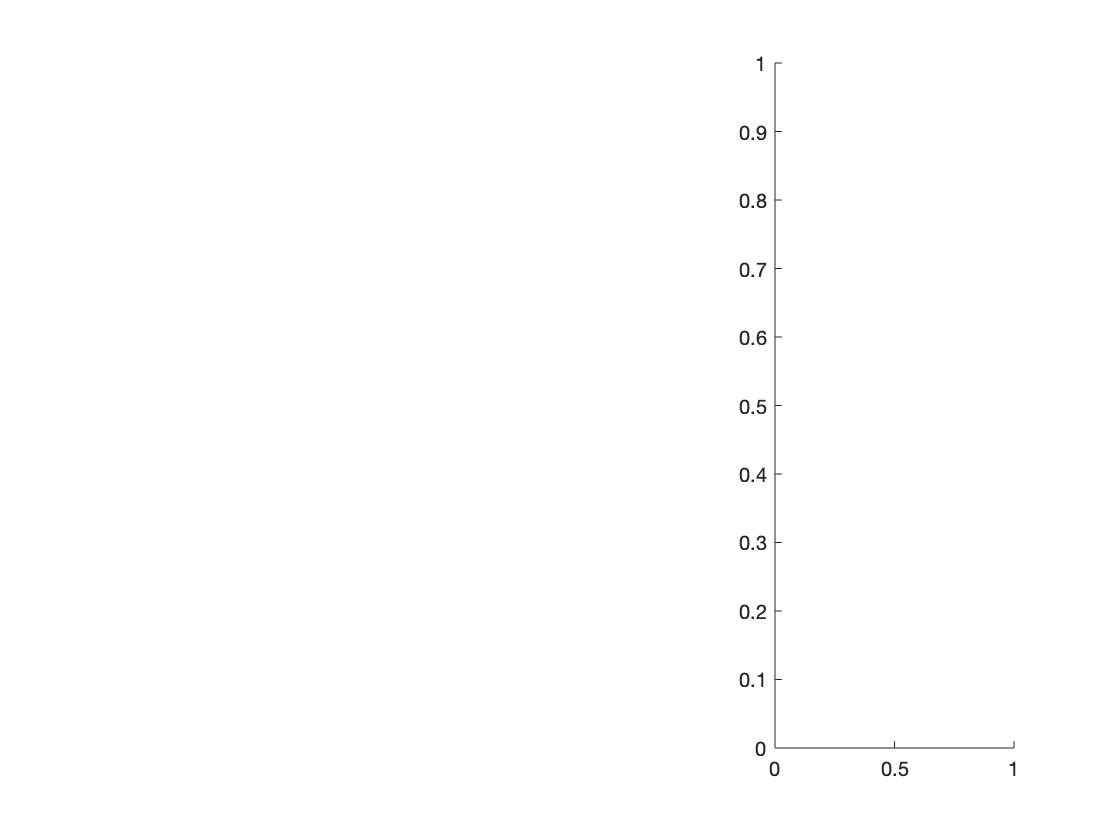

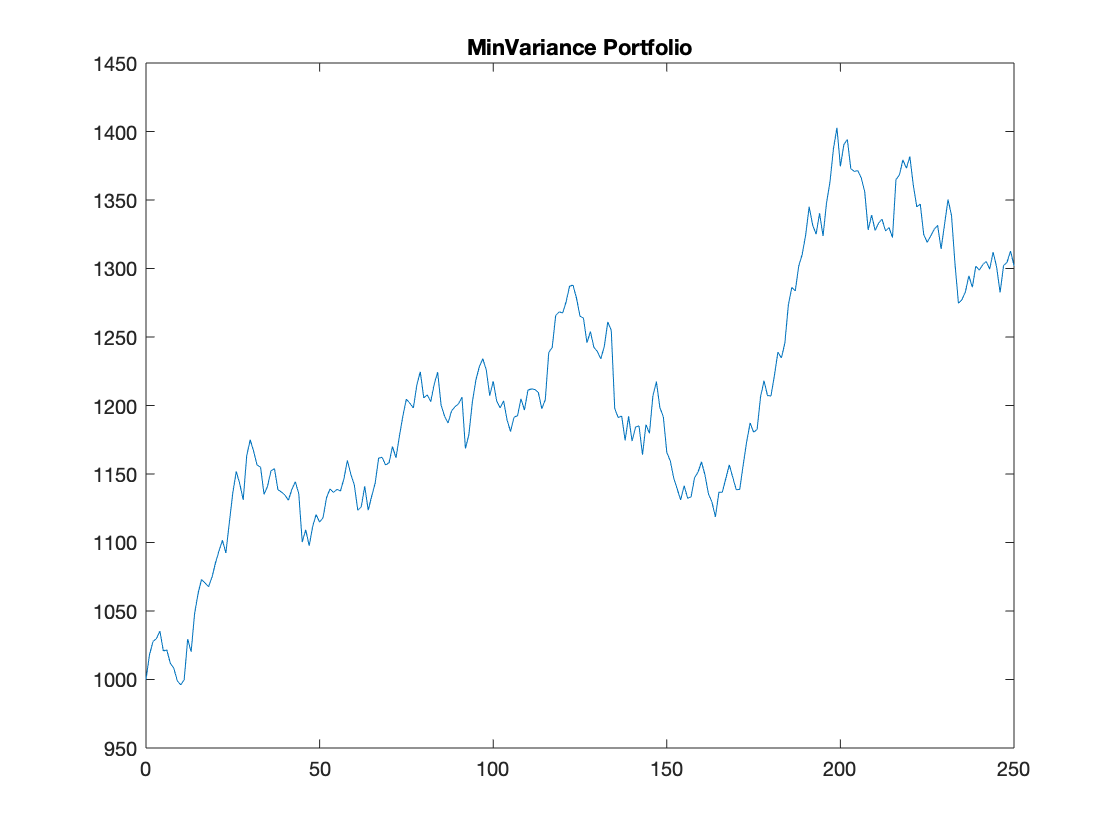

rng(2020); % ripetibilità
plotWealth = true;
num_days = 250;
num_days_update = 5;
types = ["estimated","estimatedNoShort","minvariance"];
for type = 1:length(types)
    subplot(1, 3, type)
    estimated_portfolio(numRepl, trueMu, trueSigma, lambda, num_days, types(type), plotWealth, numPastDays, num_days_update);
end

## Impatto degli errori sui premi per il rischio o sulle covarianze

%%
%Hanno più impatto errori sui premi per il rischio o sulle
%covarianze/correlazioni?? errori sui premi per il rischio, PERCHE'????
numRepl = 1000;
plotWealth = false;
rng(2020);
[wealth,w] = estimated_portfolio(numRepl, trueMu, trueSigma, lambda, num_days, 'optimal', plotWealth, numPastDays);


%applichiamo piccola variazione sulla stima (errore di stima) e aumenta
%variabilità sia in positivo che in negativo
muVariation = zeros(length(trueMu),1);
muVariation(5) =  0.001;
muVariation(10) = -0.001;
rng(2020);
[wealthVar,wVar] = estimated_portfolio(numRepl, trueMu+muVariation, trueSigma, lambda, num_days, 'estimated', plotWealth, numPastDays);

%il valore medio più basso senza variazione ma anche meno variabilità,
%intesa sia come perdita che guadagno
meanOptimal = mean(wealth(:,end))

meanOptimal =        2484.76


meanVariation = mean(wealthVar(:,end))

meanVariation =        4080.03


stdOptimal = std((wealth(:,end)))

stdOptimal =        1324.96


stdVariation = std((wealthVar(:,end)))

stdVariation =        9636.73


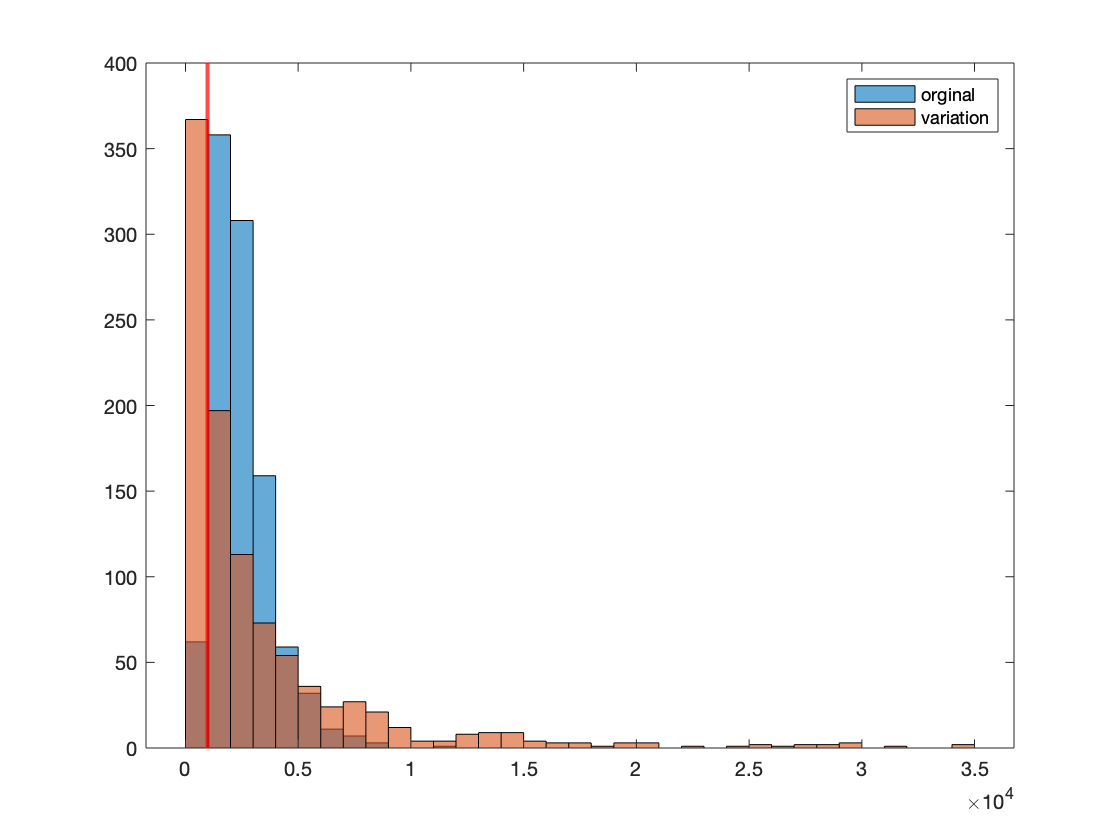


figure
histogram(wealth(:,end),35,'BinLimits',[0,35000])
hold on
histogram(wealthVar(:,end),35,'BinLimits',[0,35000])
xline(1000,'r','LineWidth',2);
legend('orginal','variation')

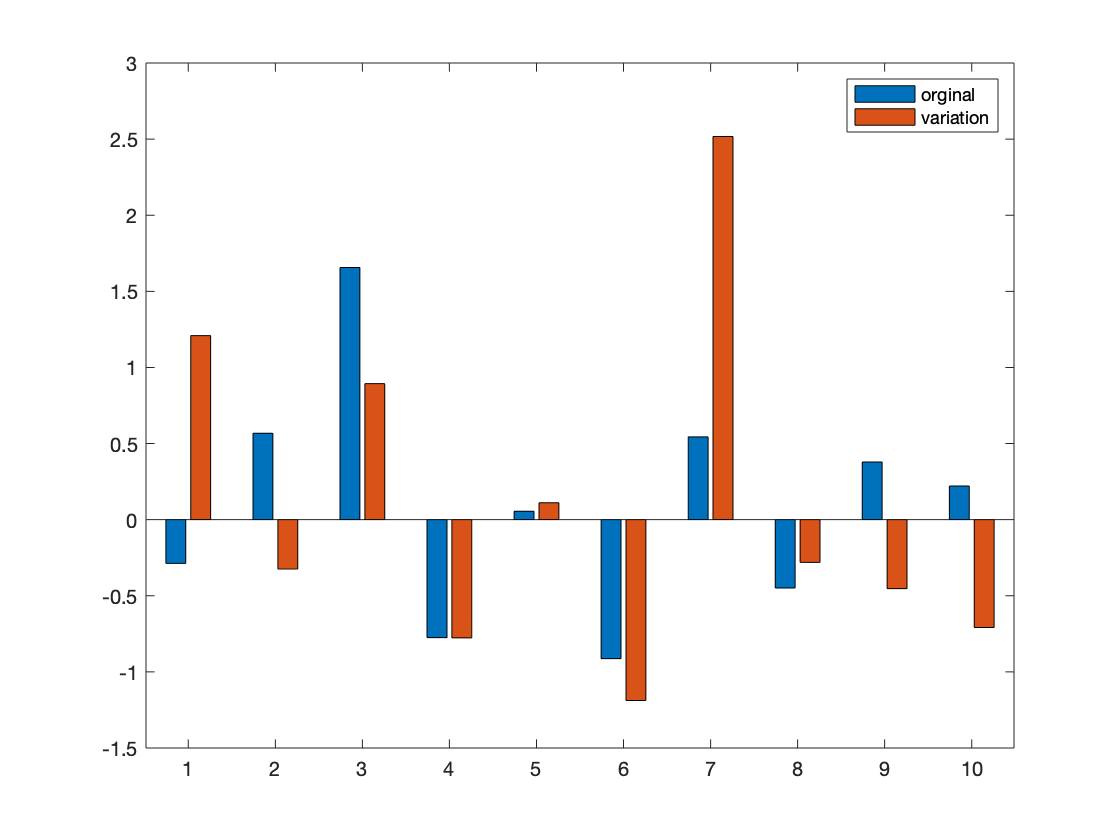


figure
bar([w(1,:)' wVar(1,:)'])
legend('orginal','variation')

## **Conclusione**

## **Appendice**

**Funzione *****QuadFolio***

La funzione riceve in ingresso un vettore di valori attesi, uno per ciascun asset che è possibile inserire nel portafoglio, la matrice di varianza-covarianza tra i diversi asset, ed infine il coefficiente di avversione al rischio che deve essere fissato. Si può dimostrare che andando a risolvere il problema di ottimizzazione questa è la formula corretta per calcolare i pesi ottimali che ci garantiscono la massimizzazione della funzione 

function [wp,mup,sigmap] = QuadFolio(expRet, covMat, lambda)
n = length(expRet);
iVet = ones(n,1);
mu = expRet(:);
invSigma = inv(covMat);
charII = iVet' * invSigma * iVet;
charIM = iVet' * invSigma * mu;
wp = invSigma*iVet/charII + ...
 1/lambda * (charII*invSigma*mu - charIM*invSigma*iVet)/charII;
mup = wp'*mu;
sigmap = sqrt(wp' * covMat * wp);
end

#### **Funzione *****estimated_portfolio***

La funzione ha lo scopo di calcolare i pesi in ciascun asset all'interno del portafoglio ottimo e il rendimento finale atteso se si decide di investire proprio in quel asset. La funzione riceve in ingresso, nell'ordine:

- *numRepl*: il numero di replicazioni da simulare

- *trueMu*:un vettore con i valori attesi

- *trueSigm*a:la matrice di varianza-covarianza

- *lambda*:il coefficiente di avversione al rischio

- *num_days*: indica su quanti giorni siamo interessati a calcolare il rendimento 

- *type:* che è una stringa che ci dice quale portafoglio ottimo siamo interessati a considerare

- *plotWealth*: una variabile binaria che ci dice se abbiamo bisogno di disegnare il diagramma a barre dei pesi del portafoglio investiti nei diversi asset

-  *numPastDays*: una variabile opzionale che indica eventualmente il numero di campioni da estrarre per ogni simulazione

- *num_days_update* : un parametro opzionale che ci dice dopo quanti giorni viene aggiornato il portafoglio.

Supponiamo arbitrariamente di considerare una ricchezza iniziale di 1000 euro. Analizziamo gli specifici casi a seconda della stringa che troviamo nella variabile *type*:

- ***‘optimal’*** : stiamo cercando i pesi del portafoglio ottimo quando abbiamo a disposizione il vettore dei valori attesi e la matrice di varianza-covarianza veri. Quindi questi ultimi e il coefficiente di avversione al rischio vengono passati alla funzione *QuadFolio *che calcola i diversi pesi con il vincolo che la loro somma sia pari ad uno.

- ***‘optimalNoShort’*** : stiamo cercando i pesi del portafoglio ottimo quando abbiamo a disposizione il vettore dei valori attesi e la matrice di varianza-covarianza veri. Tuttavia questa volta non è ammessa la vendita allo scoperto. Quindi utilizziamo la funzione *quadprog*già implementata in Matlab per calcolare i pesi che questa volta saranno tutti positivi o nulli.

- ***‘estimated’*** : stiamo cercando i pesi del portafoglio ottimo quando NON abbiamo a disposizione il vettore dei valori attesi e la matrice di varianza-covarianza reali. Quindi assumiamo che questi ultimi seguano una distribuzione normale multivariata con media il vettore dei valori attesi e matrice di covarianza uguale a quella reale. Estraiamo quindi da questa distribuzione tanti campioni quanti sono stati passati alla funzione nella variabile *numPastDays* e calcoliamo il valore atteso e la matrice di covarianza campionari e, assieme al coefficiente di avversione al rischio, li passiamo alla funzione *QuadFolio *che calcola i diversi pesi con il vincolo che la loro somma sia pari ad uno.

- ***‘estimatedNoShort’*** : esattamente come nel caso precedente, ma questa volta assumiamo che non sia possibile fare vendita allo scoperto, quindi dopo aver stimato il vettore dei valori attesi e la matrice di varianza-covarianza, li passiamo alla funzione *quadprog* con il vincolo che i pesi siano tutti non negativi.

- ***‘minvariance’*** : supponiamo ancora di NON avere a disposizione il vettore dei valori attesi e la matrice di varianza-covarianza reali. Questa volta però andiamo a calcolare il portafoglio di minima varianza, quindi dopo aver calcolato solamente la matrice di covarianza campionaria la passiamo alla funzione quadprog dove però consideriamo una funzione obiettivo dove non entrano i valori attesi.

- ***‘naive’*** : supponiamo di NON avere alcuna informazione sulla distribuzione degli elementi di cui abbiamo bisogno. La scelta più immediata e semplice, che non necessariamente risulta essere sbagliata, è quella del portafoglio naive. Questa scelta consiste nell’allocare la stessa quantità di ricchezza iniziale in ciascun asset.

Dopo avere calcolato tutti i pesi nei singoli asset andiamo a calcolare i rendimenti complessivi del portafoglio, uno per ciascun giorno fino all’orizzonte di tempo al quale siamo interessati.

Se inoltre alla funzione passiamo anche la variabile *num_days_update *che è un numero positivo e ci troviamo a stimare un portafoglio, vuol dire che siamo interessati a ribilanciare il nostro portafoglio nel weekend dopo le realizzazioni della settimana. Quindi il nuovo portafoglio entrerà in vigore dal lunedì mattina. Per farlo, calcoliamo il valore atteso e la matrice di covarianza campionari  dalle realizzazioni precedenti e poi li passiamo, insieme al coefficiente di avversione al rischio alla funzione *QuadFolio*(se ci troviamo nel caso *‘estimated’*) oppure alla funzione *quadprog*(con il vincolo sulla vendita allo scoperto nel caso di *‘estimatedNoShort’*oppure con una diversa funzione obiettivo per ottenere il portafoglio di minima varianza). **(VUOI SCRIVERLO MEGLIO??)**

Se infine la variabile *plot_wealth *è settata a *true* vuol dire che vorremmo avere anche il grafico della ricchezza giorno per giorno del nostro portafoglio.

function [wealth, w] = estimated_portfolio(numRepl, trueMu, trueSigma, lambda, num_days, type, plotWealth, numPastDays, num_days_update)

%numPastDays = 250;
options = optimoptions('quadprog','Display','none');
w = zeros(numRepl,length(trueMu));
wealth = zeros(numRepl,num_days+1);
wealth(:,1) = 1000;

for i=1:numRepl
    
    switch type
        case 'optimal'
            w(i,:) = QuadFolio(trueMu, trueSigma, lambda);
        case 'optimalNoShort'
            w(i,:) = quadprog(lambda*trueSigma,-trueMu,-eye(length(trueMu)),zeros(length(trueMu),1),ones(1,length(trueMu)),1,[],[],[],options);
        case 'estimated'
            returnsObs = mvnrnd(trueMu,trueSigma,numPastDays);
            hatMu = mean(returnsObs);
            hatSigma = cov(returnsObs);
            w(i,:) = QuadFolio(hatMu, hatSigma, lambda);
        case 'estimatedNoShort'
            returnsObs = mvnrnd(trueMu,trueSigma,numPastDays);
            hatMu = mean(returnsObs);
            hatSigma = cov(returnsObs);
            w(i,:) = quadprog(lambda*hatSigma,-hatMu,-eye(length(hatMu)),zeros(length(hatMu),1),ones(1,length(hatMu)),1,[],[],[],options);
        case 'minvariance'
            returnsObs = mvnrnd(trueMu,trueSigma,numPastDays);
            hatSigma = cov(returnsObs);
            w(i,:) = quadprog(lambda*hatSigma,[],[],[],ones(1,size(hatSigma,1)),1,[],[],[],options);
        case 'naive'
            w(i,:) = 1/length(trueMu)*ones(length(trueMu), 1);
        otherwise
            error('Error of the type')
    end
    
    for day=1:num_days
        returnDay = mvnrnd(trueMu,trueSigma);
        wealth(i,day+1) = wealth(i,day)*(1 + dot(w(i,:),returnDay));
        
        %se si aggiornano i pesi dopo num_days_update giorni
        if exist('num_days_update','var') && num_days_update > 0 && (strcmp(type,'estimated') || strcmp(type,'estimatedNoShort') || strcmp(type,'minvariance'))
            returnsObs(end+1,:) = returnDay;
            if mod(day+1,num_days_update) == 0 && day ~= 1
                hatMu = mean(returnsObs);
                hatSigma = cov(returnsObs);
                switch type
                    case 'estimated'
                        w(i,:) = QuadFolio(hatMu, hatSigma, lambda);
                    case 'estimatedNoShort'
                        w(i,:) = quadprog(lambda*hatSigma,-hatMu,-eye(length(hatMu)),zeros(length(hatMu),1),ones(1,length(hatMu)),1,[],[],[],options);
                    case 'minvariance'
                        w(i,:) = quadprog(lambda*hatSigma,[],[],[],ones(1,size(hatSigma,1)),1,[],[],[],options);
                end
            end
        end
    end
    
    if plotWealth
        figure
        switch type
            case 'optimal'
                myTitle = "Optimal Portfolio";
            case 'optimalNoShort'
                myTitle = "Optimal Portfolio with no short selling";
            case 'estimated'
                myTitle = "Estimated Portfolio";
            case 'estimatedNoShort'
                myTitle = "Estimated Portfolio with no short selling";
            case 'minvariance'
                myTitle = "MinVariance Portfolio";
            case 'naive'
                myTitle = "Naive Portfolio";
            otherwise
                error('Error of the type')
        end
        plot(0:num_days,wealth(i,:))
        title(myTitle)
    end %if plotWealth
end
end